# Assignment 1

## Data Pre-processing

% 0. Clear environment and remove all plots
clc % clears the command window
close all %removes all figures
clear % clears the workspace

% 1. Load the data
% 1.1 Loading the excel file into matlab
fileName =  "C:\Users\User\OneDrive - University of Cape Town\Notes Honours 2025\Portfolio Theory\Portfolio_Theory_A1\Data\PT-DATA-ALBI-JIBAR-JSEIND-Daily-1994-2017.xlsx";
isfile(fileName)

ans = logical
   1


excelSheetNames = sheetnames(fileName);
% 1.2 Preallocate cell array before looping
data{numel(excelSheetNames)} = [];
% 1.3 Load the dataset by sheet
for sheet = 1:numel(excelSheetNames)
    data{sheet} = readtimetable(fileName, 'Sheet', excelSheetNames{sheet}, 'VariableNamingRule', 'preserve');
end

% 2. Filter and Clean Data: Keep Only Relevant Tickers and Columns
% 2.1 Define a list of all the assets we want to include in the universe
%      - Includes RATESTEFI, ALBI, key J-bonds, variable J5x tickers, and major JSE indices
variableTickers = string("J5" + (10 : 10 : 90));
entities = {'RATESTEFI', 'RATEJ2Y4', 'ALBI', 'J203', 'J500', 'J330', 'J331', variableTickers{:}};
% 2.2 Loop over each sheet in the dataset
for i = 1:numel(data)
    % 2.2.1 Keep only TRI (Total Return Index) columns for sheets 3 and 4
    if i == 3
        allVarTable = data{i}; 
        TRITable = allVarTable(:, (3:3:27));   % select every 3rd column (TRI)
        TRITable = TRITable(4:end,:);          % remove the first 3 rows (NaNs)
        % Convert all columns to numeric if they are cells/strings 
        % (i.e. J500 needs converting)
        for col = 1:width(TRITable)
            colName = TRITable.Properties.VariableNames{col};
            % Check if the column is cell or string
            if iscell(TRITable.(colName)) || isstring(TRITable.(colName))
                TRITable.(colName) = str2double(TRITable.(colName));  % convert to numeric
            end
        end
        data{i} = TRITable;
    elseif i == 4
        allVarTable = data{i};
        allVarTable = removevars(allVarTable, ["SOURCE68779","Var2"]); % remove unwanted columns
        TRITable = allVarTable(:, (4:4:19));   % select every 4th column (TRI)
        TRITable = TRITable(4:end,:);           % remove the first 3 rows (NaNs)
        data{i} = TRITable;
    else
        % 2.2.2 For other sheets, just skip the first 3 rows
        data{i} = data{i}(4:end, :);  
    end
    % 2.3 Match column names to entities (whitelist)
    opts = data{i}.Properties;                  % get table properties
    variableMatch = zeros(size(opts.VariableNames));  % preallocate array for matching
    % 2.3.1 Perform string comparison for column matching
    if i == 2 
        % Sheet 2: compare first 8 characters to avoid unwanted matches
        for k = 1:numel(entities)
            variableMatch(strncmp(opts.VariableNames, entities{k}, 8)) = k;
        end
    else
        % Other sheets: compare first 4 characters
        for k = 1:numel(entities)
            variableMatch(strncmp(opts.VariableNames, entities{k}, 4)) = k;
        end
    end
    % 2.3.2 Identify and remove columns not in the whitelist
    idx = find(variableMatch == 0);                    % find unwanted tickers
    tickersToBeRemoved = opts.VariableNames(idx);      % get their names
    data{i} = removevars(data{i}, tickersToBeRemoved); % remove them from the table
    % 2.4 Clean up remaining column names
    %      - Remove any text after ':' to simplify variable names
    hasColon = contains(data{i}.Properties.VariableNames, ':');     
    data{i}.Properties.VariableNames(hasColon) = extractBefore(data{i}.Properties.VariableNames(hasColon), ':');
end

% 3. Clean and convert into a single timetable
allDataTable = synchronize(data{1},data{2},data{3},data{4});
%Rename variables
allDataTable = renamevars(allDataTable,{'RATESTEFI','RATEJ2Y4','J203'}, {'STEFI','JIBAR','ALSI'});

% 4. Down-sample (by decimation)
% 4.1 Decimate the daily data to monthly data
allDataTable = convert2monthly(allDataTable); % Home -> Add-ons -> Financial Toolbox

% 5. Visualising and Handling Missing Data
% 5.1 Initial Missing Data Visualisation
figure;
subplot(1,6,1);
spy(isnan(table2array(allDataTable)));
ylabel("Assets Index")
xlabel("Date Index")
title("Missing Data")
% 5.2  Fill Missing Data with Zero-Order Hold (Last Observation Carried Forward)
allDataTableFilled = fillmissing(allDataTable,'previous');
subplot(1,6,2);
spy(isnan(table2array(allDataTableFilled)));
% 5.3 Remove Rows Using the Asset With The Least NaN's (best proxy asset)
[minNans,idx] = min(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy = allDataTable.Properties.VariableNames{idx}; % Find the column with the FEWEST missing values
allDataTable = rmmissing(allDataTable,"DataVariables",rmmissingProxy); % Remove rows where the proxy has NaNs
subplot(1,6,3);
spy(isnan(table2array(allDataTable)));
% 5.4 Drop a Specific Variable (J500 - discontinued)
idxJ500=contains(allDataTable.Properties.VariableNames,'J500');
idx = 1:width(allDataTable);
allDataTable = allDataTable(:,idx(~idxJ500))

allDataTable = 261×14 timetable
       Time        ALBI    JIBAR    STEFI     J510      J520      J530      J540      J550      J560      J580      J590     J331    J330     ALSI 
    ___________    ____    _____    _____    ______    ______    ______    ______    ______    ______    ______    ______    ____    ____    ______

    30-Jun-1995    NaN      NaN      NaN     357.54    493.64    232.92    512.36    992.26    526.97    476.25    695.15    NaN     NaN      36

subplot(1,6,4);
spy(isnan(table2array(allDataTable)));
% 5.5 Remove Rows Using the Asset With the Most NaNs
% Clean rows with missing data using the asset with the most gaps as a proxy.
[countNans,idx] = max(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy =  allDataTable.Properties.VariableNames{idx};
allDataTable0 = rmmissing(allDataTable,"DataVariables",rmmissingProxy);
% 5.6 Remove Leading Rows with Missing Data
% Detect rows at the start of the dataset that contain NaNs and trim them
idx = isnan(allDataTable{:,:});
allDataTable = allDataTable(max(find(idx,max(max(cumsum(idx)))))+1:end,:);
subplot(1,6,5);
spy(isnan(table2array(allDataTable)));
% 5.7 Remove Trailing Rows and Fill Remaining Missing Data
countNans = max(max(cumsum(isnan(allDataTable{:,:}))));
allDataTable = allDataTable(1:end-countNans+1,:);
allDataTableFilled = fillmissing(allDataTable,'previous')

allDataTableFilled = 146×14 timetable
       Time         ALBI     JIBAR    STEFI      J510      J520      J530      J540      J550      J560      J580      J590      J331      J330      ALSI 
    ___________    ______    _____    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    30-Nov-2004    205.71     7.45    151.87    1188.4    1852.5    913.29    1435.4      2402    2984.3    1649.3    901.26

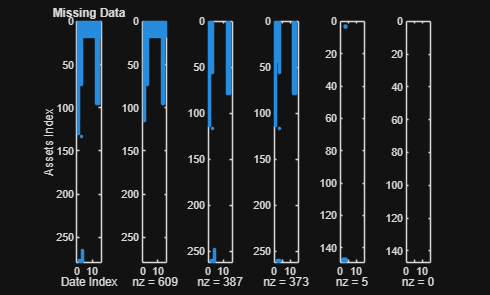

subplot(1,6,6);
spy(isnan(table2array(allDataTableFilled)));

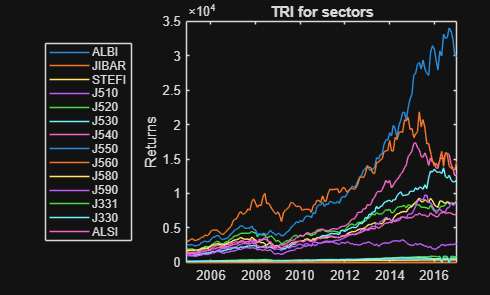


% 6. Visualise the data and the returns on a single plot
% 6.1 Compute simple returns (Rt = (Pt - Pt-1)/Pt-1)
allDataReturnsTable = tick2ret(allDataTable,'Method','Simple');
% 6.2 Plot of the time series
figure;
plot(allDataTable.Time,allDataTable{:,:})
ylabel("Returns")
title("TRI for sectors")
legend(allDataTable.Properties.VariableNames,Location="westoutside")

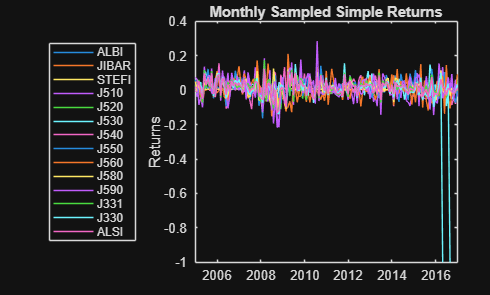

% 6.3 Plot of returns
figure;
plot(allDataReturnsTable.Time,allDataReturnsTable{:,:})
ylabel("Returns")
title("Monthly Sampled Simple Returns")
legend(allDataTable.Properties.VariableNames,Location="westoutside")

% 6.4 Handle outlier (J330 and J331)
outlierIdx = allDataReturnsTable.("J330") < -0.5;
outlierRows = find(outlierIdx); 
disp(table( ...
    outlierRows, ...
    allDataReturnsTable.Time(outlierRows), ...
    allDataReturnsTable.("J330")(outlierRows), ...
    allDataReturnsTable.("J331")(outlierRows), ...
    'VariableNames', {'RowIndex', 'Date', 'J330_Return', 'J331_Return'})); % Display the outliers

    RowIndex       Date        J330_Return    J331_Return
    ________    ___________    ___________    ___________

      137       30-Apr-2016        -1             -1     
      141       31-Aug-2016        -1             -1     



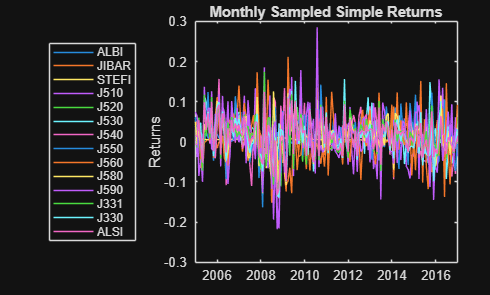

allDataReturnsTable.("J330")(outlierIdx) = NaN; % set the outliers to NaN
allDataReturnsTable.("J331")(outlierIdx) = NaN; % set the outliers to NaN
% 6.5 Plot of returns without the outliers
figure;
plot(allDataReturnsTable.Time,allDataReturnsTable{:,:})
ylabel("Returns")
title("Monthly Sampled Simple Returns")
legend(allDataTable.Properties.VariableNames,Location="westoutside")


% 7. Manage Missing Data
% 7.1 Check if there is still missing data or cells of zero
any(isnan(allDataReturnsTable{:,:}))

ans = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   1   1   0


nZeros = sum(allDataTable{:,:} == 0,'all');
disp(['Total zero values: ', num2str(nZeros)]);

Total zero values: 4


% 7.2 Compute the Arithmetic means correcting for missing data (NAN)
portfolioMean = mean(allDataReturnsTable{:,:},'omitnan');
portfolioStdDev = std(allDataReturnsTable{:,:},1,'omitnan');
portfolioVariance = var(allDataReturnsTable{:,:},'omitnan');
% 7.3 Fill those missing values with the previous results
allDataTable{:,:}(allDataTable{:,:} == 0) = NaN; % Replace zeros with NaN
allDataTable = fillmissing(allDataTable,'previous'); % Replace NaNs with the previous observation



## Experiment 1: In-Sample and Out-Of-Sample Sharpe Ratios (N-asset allocation)

% 1. Split into two sets of data
% 1.1 Number of observations
nObs = size(allDataTable,1);
% 1.2 Choose a split point (e.g. 70% training, 30% test)
splitPoint = floor(0.7 * nObs);
% 1.3 Also keep the dates if you need them
train = allDataTable(1:splitPoint,:);
test  = allDataTable(splitPoint+1:end,:);
disp(['Training rows: ', num2str(size(train,1))]);

Training rows: 102


disp(['Test rows: ', num2str(size(test,1))]);

Test rows: 44


### Training

#### Set-up

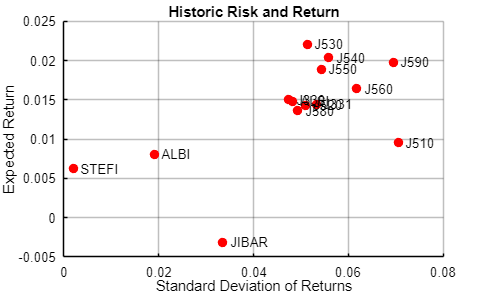

% 2. Portfolio Training Set Up
% 2.1 Compute simple returns (Rt = (Pt - Pt-1)/Pt-1)
trainReturns = tick2ret(train,'Method','Simple'); % Can replace with "Continuos"
trainReturns = fillmissing(trainReturns,'previous');
% 2.2 Create a Portfolio Object
q = Portfolio('AssetList', trainReturns.Properties.VariableNames);
% 2.3 Add mean and standard deviation of portfolio returns 
q = estimateAssetMoments(q, trainReturns{:,:}); % Arithmetic mean and covariance

% 3. Visulaise the Risk-Return Relationship
assetRisk = sqrt(diag(q.AssetCovar));
assetReturn = q.AssetMean;
assetNames = q.AssetList;
% 3.1 Labelled Graph
figure('Color', 'w');            % figure background white
scatter(assetRisk, assetReturn, 50, 'r', 'filled'); % red dots
grid on;
xlabel('Standard Deviation of Returns');
ylabel('Expected Return');
title('Historic Risk and Return');
hold on;
% 3.2 Add black labels for each asset
for i = 1:length(assetNames)
    text(assetRisk(i), assetReturn(i), ['  ' assetNames{i}], ...
         'FontSize', 10, 'Color', 'k');  % 'k' = black
end
% 3.3 Formating
ax = gca;
ax.Color = 'w';                   % axes background white
ax.XColor = 'k';                  % x-axis color black
ax.YColor = 'k';                  % y-axis color black
ax.GridColor = [0 0 0];           % grid lines black
ax.Title.Color = 'k';             % title black

#### Fully invested portfolio with varying risk aversion

% 4.1 Create the range of risk aversion parameters
lambda = linspace(-0.25,0.25,45);

% 4.2 Fully Invested
q.AEquality = ones(1,length(q.AssetMean));
q.bEquality = 1;
PortWts = NaN(length(lambda),length(q.AssetMean));

% 4.3 Find the optimal portfolio weights
for i = 1:length(lambda)
    f = - lambda(i) * q.AssetMean; % This moves the solution up along the efficient frontier
    H = q.AssetCovar; %the covariance matrix
    PortWts(i,:) = quadprog(H,f,[],[],q.AEquality,q.bEquality) ;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


% 4.4 Compute Portfolio Risk and Return
ret = estimatePortReturn(q, PortWts');
rsk = estimatePortRisk(q,PortWts');
checkPortfolioWeights(PortWts);

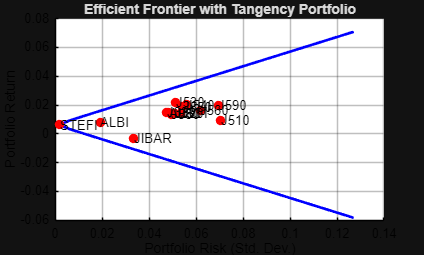


% 4.5 Plot the Curve
figure;
hold on;
% 4.5.1 Plot Efficient Frontier
plot(rsk, ret, 'b-', 'LineWidth', 2); 
% 4.5.2 Plot Individual Assets
scatter(sqrt(diag((q.AssetCovar))),  q.AssetMean, 50, 'r', 'filled');  % make all points red
text(sqrt(diag((q.AssetCovar))), q.AssetMean, assetNames, 'Color','k', 'FontSize', 10);
grid on;
% 4.5.3 Formatting
xlabel('Portfolio Risk (Std. Dev.)');
ylabel('Portfolio Return');
title('Efficient Frontier with Tangency Portfolio');
% 4.6.4 Formatting
ax = gca;
ax.Color = 'w';       % axes background
ax.XColor = 'k';      % x-axis labels
ax.YColor = 'k';      % y-axis labels
ax.GridColor = [0 0 0];  % grid lines black
hold off;

#### Fully invested portfolio with varying risk aversion + Excluding Cash and Market Indices

% 5.1.1 Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI', 'JIBAR','ALSI', 'J330','J331'})

tickers = 1×9 cell array
    {'ALBI'}    {'J510'}    {'J520'}    {'J530'}    {'J540'}    {'J550'}    {'J560'}    {'J580'}    {'J590'}


Returns = trainReturns{:,tickers};

% 5.1.2 Calculate the mu and sigma without changing the q portfolio object
mu = mean(Returns); % ***Added**
Sigma = cov(Returns); % ***Added**

% 5.2 Create the range of risk aversion parameters
lambda = linspace(-0.25,0.25,45);

% 5.3 Fully Invested (don't change the q portfolio object) ***Changed**
Aeq = ones(1,length(mu)); 
beq = 1;
PortWts = NaN(length(lambda),length(mu));

% 5.4 Find the optimal portfolio weights
optionsQP = optimset('quadprog')';
optionsQP= optimset(optionsQP,'Display','off');
for i = 1:length(lambda)
    f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
    H = Sigma; %the covariance matrix
    [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,[],[],Aeq,beq,[],[],[],optionsQP); % ***Changed**
end

% 5.5 Compute Portfolio Risk and Return with no cash assets ***Changed**
ret0 = PortWts * mu';
rsk0 = sqrt(diag(PortWts * Sigma * PortWts'));
checkPortfolioWeights(PortWts);

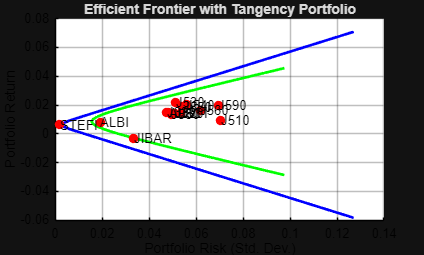


% 5.6 Plot the Curve
figure;
hold on;
% 5.6.1 Plot Efficient Frontier
plot(rsk, ret, 'b-', 'LineWidth', 2);  
plot(rsk0, ret0, 'g-', 'LineWidth', 2);  
% 5.6.2 Plot Individual Assets
scatter(sqrt(diag((q.AssetCovar))),  q.AssetMean, 50, 'r', 'filled');  % make all points red
text(sqrt(diag((q.AssetCovar))), q.AssetMean, assetNames, 'Color','k', 'FontSize', 10);
grid on;
% 5.6.3 Formatting
xlabel('Portfolio Risk (Std. Dev.)');
ylabel('Portfolio Return');
title('Efficient Frontier with Tangency Portfolio');
% 5.6.4 Formatting
ax = gca;
ax.Color = 'w';       % axes background
ax.XColor = 'k';      % x-axis labels
ax.YColor = 'k';      % y-axis labels
ax.GridColor = [0 0 0];  % grid lines black
hold off;

#### Fully invested portfolio with varying risk aversion + Excluding Cash and Market Indices + No short selling constraint (method 1)

% 6.1.1 Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','ALSI','JIBAR', 'J330','J331'})

tickers = 1×9 cell array
    {'ALBI'}    {'J510'}    {'J520'}    {'J530'}    {'J540'}    {'J550'}    {'J560'}    {'J580'}    {'J590'}


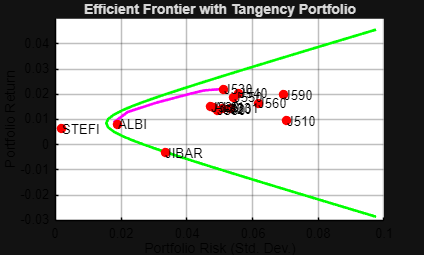

Returns = trainReturns{:,tickers};
% 6.1.2 Calculate the mu and sigma without changing the q portfolio object
mu = mean(Returns);
Sigma = cov(Returns);

% 6.2 Create the range of risk aversion parameters
lambda = linspace(0,1,25);

% 6.3 Fully Invested (don't change the q portfolio object)
Aeq = ones(1,length(mu));
beq = 1;
PortWts = NaN(length(lambda),length(mu));

% 6.4 No Short-selling (inequality constraint) ***Added**
A = -eye(length(mu));
b = zeros(length(mu),1);

% 6.5 Find the optimal portfolio weights
optionsQP = optimset('quadprog')';
optionsQP= optimset(optionsQP,'Display','off');
for i = 1:length(lambda)
    f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
    H = Sigma; %the covariance matrix
    [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,A,b,Aeq,beq,[],[],[],optionsQP); % ***Changed**
end

% 6.6 Compute Portfolio Risk and Return with no cash assets + no selling ***Changed**
ret1 = PortWts * mu';
rsk1 = sqrt(diag(PortWts * Sigma * PortWts'));
checkPortfolioWeights(PortWts)

% 6.7 Plot the Curve
figure;
hold on;
% 6.7.1 Plot Efficient Frontier 
plot(rsk0, ret0, 'g-', 'LineWidth', 2); 
plot(rsk1, ret1, 'm-', 'LineWidth', 2); 
% 6.7.2 Plot Individual Assets
scatter(sqrt(diag((q.AssetCovar))),  q.AssetMean, 50, 'r', 'filled');  % make all points red
text(sqrt(diag((q.AssetCovar))), q.AssetMean, assetNames, 'Color','k', 'FontSize', 10);
grid on;
% 6.7.3 Formatting
xlabel('Portfolio Risk (Std. Dev.)');
ylabel('Portfolio Return');
title('Efficient Frontier with Tangency Portfolio');
% 6.7.4 Formatting
ax = gca;
ax.Color = 'w';       % axes background
ax.XColor = 'k';      % x-axis labels
ax.YColor = 'k';      % y-axis labels
ax.GridColor = [0 0 0];  % grid lines black
hold off;

#### Fully invested portfolio with varying risk aversion + Excluding Cash and Market Indices + No short selling constraint  (method 2)


% 7.1.1 Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','ALSI','JIBAR', 'J330','J331'})

tickers = 1×9 cell array
    {'ALBI'}    {'J510'}    {'J520'}    {'J530'}    {'J540'}    {'J550'}    {'J560'}    {'J580'}    {'J590'}


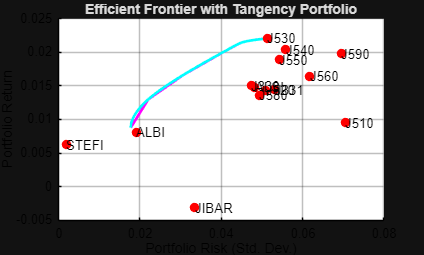

Returns = trainReturns{:,tickers};
% 7.1.2 Calculate the mu and sigma without changing the q portfolio object
mu = mean(Returns);
Sigma = cov(Returns);

% 7.2 Create the range of varying return targets
retTarget = min(ret1):((max(ret1)-min(ret1))/90):max(ret1); % ***Added***

% 7.3 Fully Invested (don't change the q portfolio object)
Aeq = ones(1,length(mu));
beq = 1;
% Equality constraint (return target) ***Added***
Aeq = [Aeq; mu];
beq = [beq; 0];
PortWts =  NaN(length(retTarget),length(mu)); % ***Changed***

% 7.4 No Short-selling (inequality constraint) 
ub = ones(length(mu),1);
lb = zeros(length(mu),1);

% 7.5 Find the optimal portfolio weights
optionsQP = optimset('quadprog')';
optionsQP= optimset(optionsQP,'Display','off');
for i = 1:length(retTarget)
    beq(2) = retTarget(i); % ***Changed*** This moves the solution up along the efficient frontier
    H = Sigma; %the covariance matrix
    [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,zeros(size(mu))',[],[],Aeq,beq,lb,ub,[],optionsQP); % ***Changed*** 
end

% 7.6 Compute Portfolio Risk and Return with no cash assets + no selling
ret2 = PortWts * mu';
rsk2 = sqrt(diag(PortWts * Sigma * PortWts'));
checkPortfolioWeights(PortWts)

% 7.7 Plot the Curve
figure;
hold on;
% 7.7.1 Plot Efficient Frontier 
plot(rsk1, ret1, 'm-', 'LineWidth', 2); 
plot(rsk2, ret2, 'c-', 'LineWidth', 2); 
% 7.7.2 Plot Individual Assets
scatter(sqrt(diag((q.AssetCovar))),  q.AssetMean, 50, 'r', 'filled');  % make all points red
text(sqrt(diag((q.AssetCovar))), q.AssetMean, assetNames, 'Color','k', 'FontSize', 10);
grid on;
% 7.7.3 Formatting
xlabel('Portfolio Risk (Std. Dev.)');
ylabel('Portfolio Return');
title('Efficient Frontier with Tangency Portfolio');
% 7.7.4 Formatting
ax = gca;
ax.Color = 'w';       % axes background
ax.XColor = 'k';      % x-axis labels
ax.YColor = 'k';      % y-axis labels
ax.GridColor = [0 0 0];  % grid lines black
hold off;

#### Fully invested portfolio with varying risk aversion + Excluding Cash and Market Indices + No short selling constraint  + Add the sharpe Ratio Maximising Portfolio

% 8.1 Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','ALSI','JIBAR', 'J330','J331'})

tickers = 1×9 cell array
    {'ALBI'}    {'J510'}    {'J520'}    {'J530'}    {'J540'}    {'J550'}    {'J560'}    {'J580'}    {'J590'}


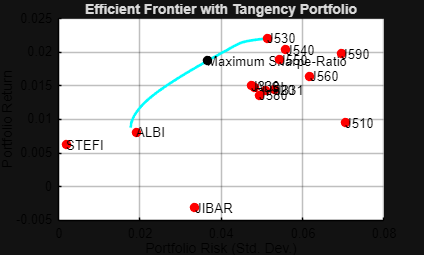

Returns = trainReturns{:,tickers};

% 8.2 Risk free rate
RFR = trainReturns{:,{'STEFI'}};

% 8.3 monthy sampled arithmetic mean of simple returns
mu = mean(Returns); 
ERFR = mean(RFR); % average risk free rate (when to use geometric average)

% 8.4 Covariance
Sigma = cov(Returns);

% 8.5 Equally weighted portfolio
x0 = ones(size(mu))/length(mu);

% 8.6 initialise the weights
Wts_train = NaN(1,length(mu));

% 8.7 objective function to maximise the SR
fn0 = @(x) (-(x*mu' - ERFR)/sqrt(x*Sigma*x'));

% 8.8 No Short-selling (upper and lower bounds)
ub = ones(length(mu),1);
lb = zeros(length(mu),1);

% 8.9 Equality constraint (fully invested)
Aeq = ones(1,length(mu));
beq = 1;

% 8.10 Use SQP to solve for the tangency portfolio
options = optimoptions(@fmincon,'Algorithm','sqp','OptimalityTolerance',1e-8,'Display','off');
Wts_train = fmincon(fn0,x0,[],[],Aeq,beq,lb,ub,[],options); % These are the optimal weights (Maximise sharpe)

% 8.11 Compute Portfoli Risk and Return of Maximized Sharpe Ratio
retSR = Wts_train*mu';
rskSR = sqrt(Wts_train*Sigma*Wts_train');
checkPortfolioWeights(Wts_train)

% 8.12 Plot the Curve
figure;
hold on;
% 8.12.1 Plot Efficient Frontier 
plot(rsk2, ret2, 'c-', 'LineWidth', 2); 
% 8.12.2 Plot Individual Assets
scatter(rskSR, retSR, 50,  'k','filled') % ***Added***
text(rskSR, retSR, "Maximum Sharpe-Ratio", 'Color','k', 'FontSize', 10);
scatter(sqrt(diag((q.AssetCovar))),  q.AssetMean,50, 'r', 'filled');  % make all points red
text(sqrt(diag((q.AssetCovar))), q.AssetMean, assetNames, 'Color','k', 'FontSize', 10);
grid on;
% 8.12.4 Formatting
xlabel('Portfolio Risk (Std. Dev.)');
ylabel('Portfolio Return');
title('Efficient Frontier with Tangency Portfolio');
% 8.12.5 Formatting
ax = gca;
ax.Color = 'w';       % axes background
ax.XColor = 'k';      % x-axis labels
ax.YColor = 'k';      % y-axis labels
ax.GridColor = [0 0 0];  % grid lines black
hold off;

#### Fully invested portfolio with varying risk aversion + Excluding Cash and Market Indices + No short selling constraint  + Add the sharpe Ratio Maximising Portfolio + Security Market Line + Visualise the Sharpe Ratio values

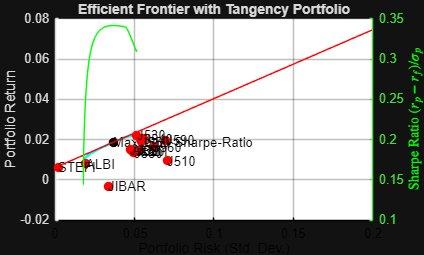

% 9.1.1 Security Market Line
hold on
% 9.1.2 SML through the tangency portfolio
SML = @(x) (ERFR + (retSR-ERFR)/rskSR*x);
x = linspace(0,0.20,20);
% 9.1.3 plot market line
plot(x,SML(x),'r')
hold off;

% 9.2.1 Plot the Sharpe Ratio against risk levels
yyaxis right
ylabel('Sharpe Ratio ${ ( r_p -r_{f} ) / \sigma_p }$','interpreter','latex','Color','g')
% 9.2.2 Plot the Sharpe Ratio against risk level
hold on
plot(rsk2,(ret2-ERFR)./rsk2,'-g')
hold off

### Testing

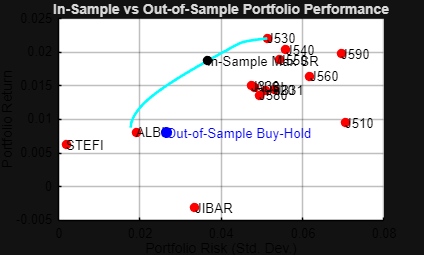

% 10. Buy-and-Hold Strategy on Test Dataset
% 10.1 Tickers we are excluding (same exclusions as training)
tickersTest = setdiff(test.Properties.VariableNames,{'STEFI','ALSI','JIBAR','J330','J331'});
testReturns = tick2ret(test,'Method','Simple'); % Can replace with "Continuos" (Same from training)
testReturns = fillmissing(testReturns,'previous');
ReturnsTest = testReturns{:,tickersTest};

% 10.2 Risk free rate for test dataset
RFR_test = testReturns{:,{'STEFI'}}; % Same as training
ERFR_test = mean(RFR_test); % average risk free rate

% 10.3 Apply Tangency Portfolio Weights from Training (Buy-and-Hold)
Wts_Tangency = Wts_train;  % from Section 8.10, trained on training dataset

% 10.4 Compute portfolio returns in test dataset
portRetTest = ReturnsTest * Wts_Tangency';   % T x 1 vector

% 10.5 Compute portfolio statistics out-of-sample
meanRetTest = mean(portRetTest);                     % mean portfolio return
stdRetTest  = std(portRetTest);                      % volatility
covTest     = cov(ReturnsTest);                      % covariance matrix (assets)
SharpeTest  = (meanRetTest - ERFR_test) / stdRetTest; % Sharpe ratio (out-of-sample)

% 10.6 Cumulative Buy-and-Hold Wealth Curve
cumRetTest = cumprod(1 + portRetTest);

% 10.7.1 Plotting In-Sample vs Out-of-Sample Performance
figure;
hold on;
% 10.7.2 In-sample efficient frontier and tangency portfolio
scatter(sqrt(diag((q.AssetCovar))),  q.AssetMean,50, 'r', 'filled');  % make all points red
text(sqrt(diag((q.AssetCovar))), q.AssetMean, assetNames, 'Color','k', 'FontSize', 10);
plot(rsk2, ret2, 'c-', 'LineWidth', 2); 
scatter(rskSR, retSR, 50, 'k', 'filled');
text(rskSR, retSR, "In-Sample Max SR", 'Color','k','FontSize',10);
% 10.7.3 Out-of-sample portfolio (Buy-and-Hold)
scatter(stdRetTest, meanRetTest, 70, 'b', 'filled');
text(stdRetTest, meanRetTest, "Out-of-Sample Buy-Hold", 'Color','b','FontSize',10);
% 10.7.4 Axes formatting
grid on;
xlabel('Portfolio Risk (Std. Dev.)');
ylabel('Portfolio Return');
title('In-Sample vs Out-of-Sample Portfolio Performance');
ax = gca;
ax.Color = 'w';
ax.XColor = 'k';
ax.YColor = 'k';
ax.GridColor = [0 0 0];
hold off;

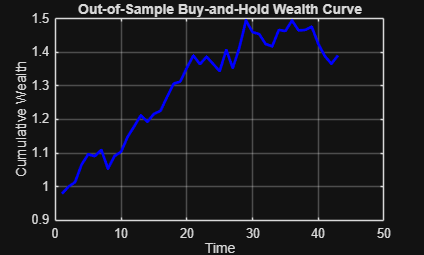


% 10.8 Plot Cumulative Wealth (Test Sample)
figure;
plot(cumRetTest,'b','LineWidth',2);
xlabel('Time');
ylabel('Cumulative Wealth');
title('Out-of-Sample Buy-and-Hold Wealth Curve');
grid on;

### Final Results

% 12.1 In-sample statistics (Tangency Portfolio from training)
SharpeTrain = (retSR - ERFR) / rskSR; % already available, redefined here for clarity
meanTrain   = retSR;
stdTrain    = rskSR;
covTrain    = Sigma; % from Section 8.4

% 12.2 Results table
ResultsComparison = table( ...
    ["In-Sample";"Out-of-Sample"], ...
    [meanTrain; meanRetTest], ...
    [stdTrain; stdRetTest], ...
    [SharpeTrain; SharpeTest], ...
    'VariableNames', {'Sample','MeanReturn','StdDev','SharpeRatio'});

disp('Comparison of In-Sample vs Out-of-Sample Performance:');

Comparison of In-Sample vs Out-of-Sample Performance:


disp(ResultsComparison);

        Sample         MeanReturn     StdDev     SharpeRatio
    _______________    __________    ________    ___________

    "In-Sample"         0.018721     0.036576      0.34148  
    "Out-of-Sample"     0.008042      0.02647      0.10914  



## Experiment 2 : Out-Of-Sample Backtesting using a Rolling Window